## Plotting Average Absolute Enzyme Concentrations

#### This script loops scatter plots for average non-optimized and optimized enzyme concentrations in a loop, creating panels for individual enzymes

Import all required data in a separate script:

import_optimization_results; %import average of ten replicates
%import_optimization_reps; % import ten replicates

Assign x and y for scatter graphs

Assign output variables to non-optimized and optimized protein data in linear and log scale: 

y = cell(1, numel(sheet_names));
y_log = cell(1, numel(sheet_names));
y_fold = cell(1, numel(sheet_names));
%y_log_fold = cell(1, numel(sheet_names)); redundant

for i = 1:numel(sheet_names)
    % Combine full data for non-optimized and optimized at each Ci
    y{1,i} = horzcat(results_data{1,1},results_data{2,i}(:,1));
    % Convert data to log scale
    y_log{1,i} = horzcat(log10(y{1,i}(:,1)),log10(y{1,i}(:,2))); % log x
    % Calculate y fold changes
    y_fold{1,i} = y{1,i}(:,2:end)./y{1,i}(:,1);
    % Calculate y_log fold changes - essentially the same as y fold since
    % the ratios of non-opt to opt are equal
    %y_log_fold{1,i} = y_log{1,i}(:,2:end)./y_log{1,i}(:,1);
end

Convert sheet_names into x values :

Ci = str2double(sheet_names);
enzymes=string(cats);

Create output variables for all enzymes:

enzyme_nopt_concs = zeros(size(cats,1),size(y,2)); 
all_opt_concs = zeros(size(cats,1),size(y,2)); 
all_opt_FC = zeros(size(cats,1),size(y,2)); 
all_opt_log_FC = zeros(size(cats,1),size(y,2)); 

Specify indices of different enzyme classes (Calvin-Benson-Bassham cycle/Photorespiration/Sucrose-Starch metabolism):

CBB_indices = 1:8;
PR_indices = 10:16;
SS_indices = [9,17:23];

Replace PR_constraints reaction IDs with enzyme names: 

PR_constraints_protein(:,1) = cellstr(enzymes(PR_indices));

Horizontally stack the lower limits for photorepiratory enzyme concentrations for each Ci by copying column 2 of PR_constraints:

PR_limits = cell2mat(repmat(PR_constraints_protein(:,2),1,15));

Loop through all sheets and extract the values for specific enzymes:

for j = 1:length(y{1,i}(:,2)) % For all enzymes
    for i = 1:numel(Ci)
    enzyme_nopt_concs(j,i) = y{1,i}(j,1); % take the non-optimized data from col 1
    all_opt_concs(j,i) = y{1,i}(j,2); % take the optimized data from col 2
    all_opt_FC(j,i) = y_fold{1,i}(j,1); 
    %all_opt_log_FC(j,i) = y_log_fold{1,i}(j,1); 
    end
end

Use a switch to choose whether to plot non-optimised vs optimised or fold changes for each enzyme panel:

plottype = input('Enter type of plot (opt/FC): ', 's');

Create CBB panel:

    figure;
    % Plot scatter graphs of Ci (x) against absolute protein concentrations of individual enzymes 
    for j = 1:length(CBB_indices) % For each enzyme j 
        CBB_index = CBB_indices(j);
        nexttile
        switch (plottype)
        case 'opt'
        %semilogy(Ci, enzyme_nopt_concs(CBB_index,:), '.', 'MarkerSize', 15);
        scatter(Ci, enzyme_nopt_concs(CBB_index,:),'black','filled','o'); % Plot non-optimized series
        hold on
        %semilogy(Ci, all_opt_concs(CBB_index,:), '^', 'MarkerSize', 15);
        scatter(Ci, all_opt_concs(CBB_index,:),'green','filled','^'); % Plot optimized series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        max_y = max(all_opt_concs(CBB_index,:)); % Check maximum value for the enzyme
        yticks(0:ceil(max_y)); % Set y-ticks from 0 to the ceiling of the maximum value
        yticks([yticks, ceil(max_y)+1]); % Add one tick interval higher than the maximum value
        ylim padded
        %ylim([0,inf]) % Protein y axis limits 
        ylim([0, ceil(max_y) + 1]);
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Average absolute protein content (mg m^{-2})','FontSize', 10);
        title(enzymes(CBB_index))
        grid on
        hold off
        legend('Non-optimized','Optimized','Location', 'SouthEastOutside')

 Plotting only one series in the case of fold changes:

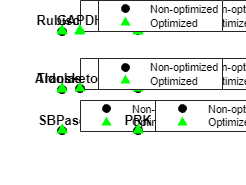

        case 'FC'
        scatter(Ci, all_opt_FC(CBB_index,:),'blue','filled','^'); % Plot fold change series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        yticks('auto') 
        ylim([0,inf]) % Protein y axis limits 
        ylim padded
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Fold change protein content','FontSize', 10);
        title(enzymes(CBB_index))
        grid on
        hold off
        end
    end
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_CBB_Enzymes"),'-dpdf','-fillpage');

Create PR panel:

figure;
% Plot scatter graphs of Ci (x) against absolute protein concentrations of individual enzymes 
for j = 1:length(PR_indices) % For each enzyme j 
    PR_index = PR_indices(j);
    nexttile
    switch (plottype)
        case 'opt'
        %semilogy(Ci, enzyme_nopt_concs(PR_index,:), '.', 'MarkerSize', 15);
        scatter(Ci, enzyme_nopt_concs(PR_index,:),'black','filled','o'); % Plot non-optimized series
        hold on
        %semilogy(Ci, all_opt_concs(PR_index,:), '^', 'MarkerSize', 15);
        scatter(Ci, all_opt_concs(PR_index,:),'green','filled','^'); % Plot optimized series
        hold on 
        % Plot PR constraints levels
        plot(Ci, PR_limits(j,:), "b--"); 
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim manual
        ylim([0,inf]) % Protein y axis limits 
        ylim padded        
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Average absolute protein content (mg m^{-2})','FontSize', 10);
        title(enzymes(PR_index))
        grid on
        hold off
        legend('Non-optimized','Optimized','Lower Limit','Location', 'SouthEastOutside')

Plotting only one series in the case of fold changes:

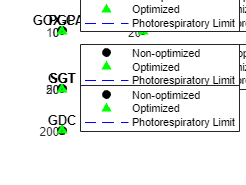

        case 'FC'
        scatter(Ci, all_opt_FC(PR_index,:),'blue','filled','^'); % Plot fold change series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        ylim padded
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Fold change protein content','FontSize', 10);
        title(enzymes(PR_index))
        grid on
        hold off
     end
end
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_PR_Enzymes"),'-dpdf','-fillpage');

Create SS panel:

figure;
% Plot scatter graphs of Ci (x) against absolute protein concentrations of individual enzymes 
for j = 1:length(SS_indices) % For each enzyme j 
    SS_index = SS_indices(j);
    nexttile
        switch (plottype)
        case 'opt'
        %semilogy(Ci, enzyme_nopt_concs(SS_index,:), '.', 'MarkerSize', 15);
        scatter(Ci, enzyme_nopt_concs(SS_index,:),'black','filled','o'); % Plot non-optimized series
        hold on
        %semilogy(Ci, all_opt_concs(SS_index,:), '^', 'MarkerSize', 15);
        scatter(Ci, all_opt_concs(SS_index,:),'green','filled','^'); % Plot optimized series
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        ylim padded
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Average absolute protein content (mg m^{-2})','FontSize', 10);
        title(enzymes(SS_index))
        grid on
        hold off
        legend('Non-optimized','Optimized','Location', 'SouthEastOutside')

Plotting only one series in the case of fold changes:

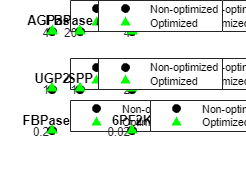

        case 'FC'
        scatter(Ci, all_opt_FC(SS_index,:),'blue','filled','^'); % Plot fold change series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        ylim padded
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Fold change protein content','FontSize', 10);
        title(enzymes(SS_index))
        grid on
        hold off
        end
end
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_SS_Enzymes"),'-dpdf','-fillpage');